fm = 5;
fc = 50;
A = 1;
T = 1;
fs = 1000;
t = 0:1/fs:T;
m = A*sin(2*pi*fm*t);

ka = 0.5;
s_am = A *(1 + ka*m).*cos(2*pi*fc*t);

init_m = cumsum(m)/fs;
kf = 50;
s_fm = A * cos(2*pi*fc*t + sin(2*pi*kf*init_m));

kp = pi/2;
s_pm = A * cos(2*pi*fc*t + kp * m);

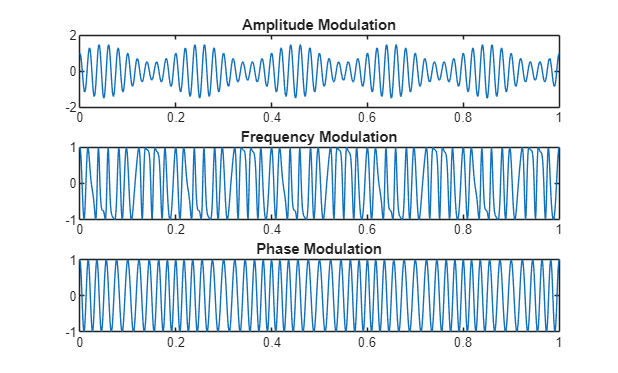

figure
subplot(3,1,1), plot(t,s_am), title("Amplitude Modulation")
subplot(3,1,2), plot(t,s_fm), title("Frequency Modulation")
subplot(3,1,3), plot(t,s_pm), title("Phase Modulation")